**Band EEG extraction **	

Load the signal eeg.mat (sampling frequency 256Hz). Do the spectral analysis and remove the artefacts.

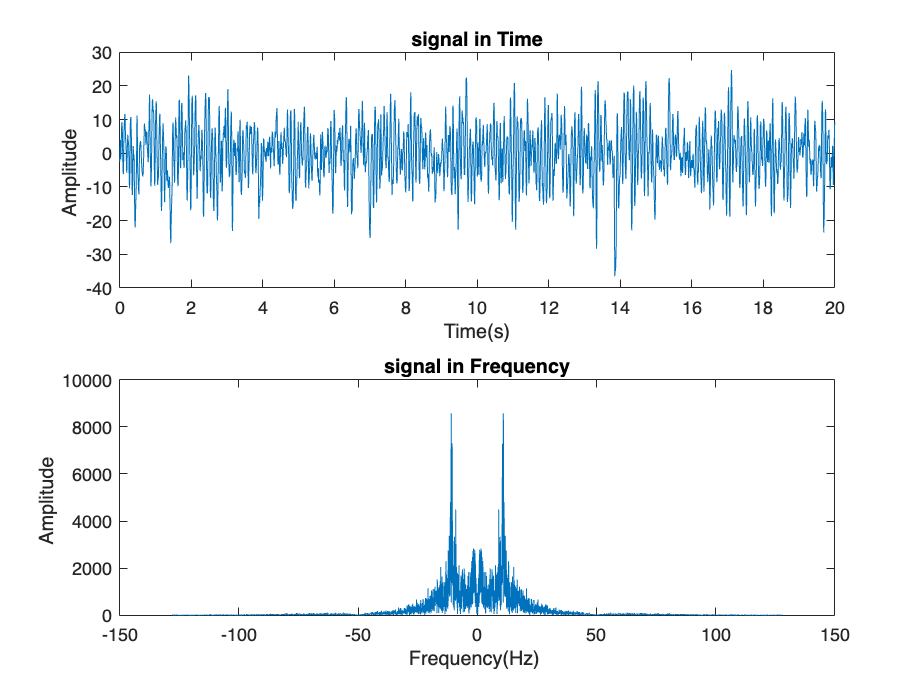

load 'eeg.mat'
fs = 256;

% n of samples n = duration*fs = length(eeg)
n = length(eeg); 

duration = n./fs;

t=linspace(0,duration,n);

f = linspace(-fs/2,fs/2,length(eeg));


figure;
subplot(2,1,1);
plot(t, eeg);
title('signal in Time');
xlabel('Time(s)');
ylabel('Amplitude ');

subplot(2,1,2);
plot(f,fftshift(abs(fft(eeg))));
title('signal in Frequency');
xlabel('Frequency(Hz) ');
ylabel('Amplitude ');


% The signal from an analysis in both time and frequency domain 
% does not show the presence of evident artefacts.


Detect the presence of the EEG basic rhythms from the EEG amplitude spectrum. Once detected, use band pass filters to obtain the single rhythms and plot them in the time domain. 


[e1,g1] = butter(3,[0.5 3]./(fs/2),'bandpass');
delta=filtfilt(e1,g1,eeg);
[e2,g2] = butter(3,[3 7]./(fs/2),'bandpass');
teta=filtfilt(e2,g2,eeg);
[e3,g3] = butter(3,[8 13]./(fs/2),'bandpass');
alfa=filtfilt(e3,g3,eeg);
[e4,g4] = butter(3,[14 30]./(fs/2),'bandpass');
beta=filtfilt(e4,g4,eeg);
[e5,g5] = butter(3,[30 100]./(fs/2),'bandpass');
gamma=filtfilt(e5,g5,eeg);


Plot each band in a different plot by using the subplot command (check the help) 

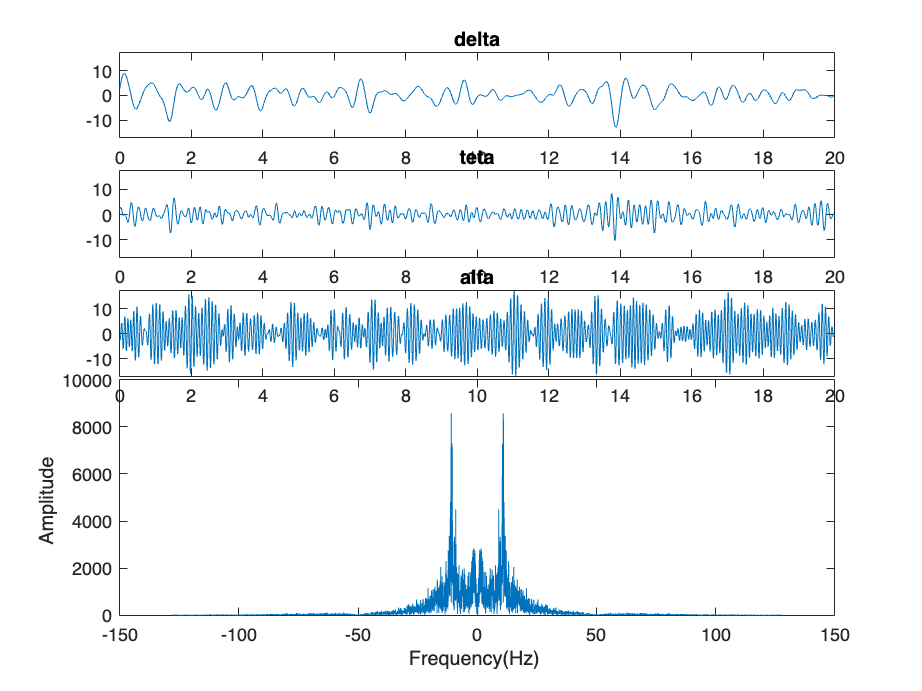

%forzare qui sugli assi y gli stessi valori di Amplitude
% per avere visualizzazioni con stesse scale di paragone

% Calcolo dei limiti comuni dell'asse y
y_min = min([delta, teta, alfa, beta, gamma], [], 'all');
y_max = max([delta, teta, alfa, beta, gamma], [], 'all');

subplot(5,1,1)
plot(t,delta)
title('delta')
ylim([y_min y_max])

subplot(5,1,2)
plot(t,teta)
title('teta')
ylim([y_min y_max])

subplot(5,1,3)
plot(t,alfa)
title('alfa')
ylim([y_min y_max])

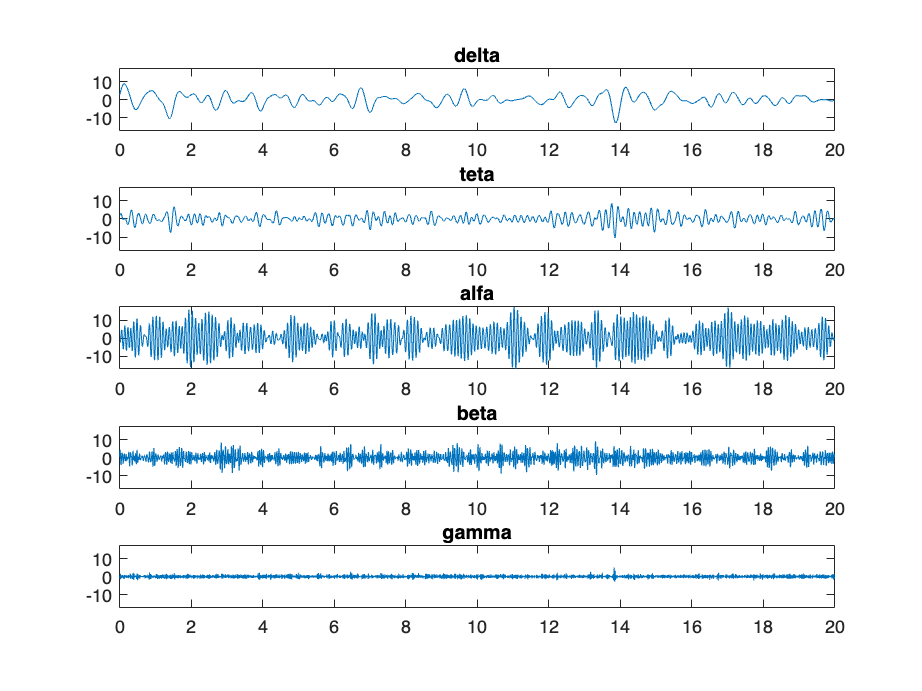


subplot(5,1,4)
plot(t,beta)
title('beta')
ylim([y_min y_max])

subplot(5,1,5)
plot(t,gamma)
title('gamma')
ylim([y_min y_max])